# **Circuitos Electricos II**

**Roberto Sanchez Figueroa    **

**brrsanchezfi@unal.edu.co**

***Monitoria Circuitos II***

***GIT-HUB:  https://github.com/brrsanchezfi/Circuitos_2022_1***

# **Soluciones propuestas para los ejercicios del taller 6**

## Ejercicio 1

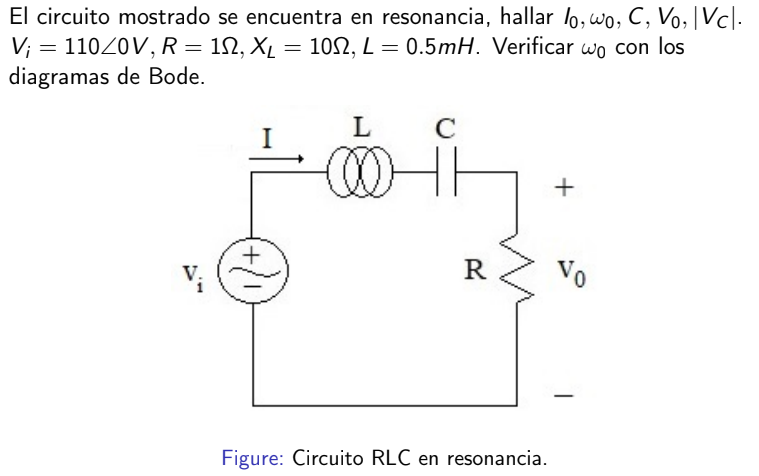

Partimos de la condicion que el circuito esta  en resonancia 

v_i_n =  pol_com(110,0)

v_i_n =    110


R_n = 1;
X_L_n = 10;
L_n = 0.5e-3;


syms v_i R X_L C v_o s L f w_o



 despejamos la frecuencia de resonancia de la formula de reactancia inductiva

ecu1 = X_L == 2*pi*f*L

$$ecu1 = X_{L}=2\,\pi \,L\,f$$

f = solve(ecu1,f)

$$f = \frac{X_{L}}{2\,L\,\pi }$$

f= subs(f,[X_L L],[X_L_n L_n]); %Hz
w_o = f*2*pi  %rad/s

$$w\_o = 20000$$

ecu2 = 

ecu2 = w_o == 1/(sqrt(L*C)) 

$$ecu2 = 20000=\frac{1}{\sqrt{C\,L}}$$

C = solve(ecu2, C);
C = subs(C,L,L_n)

$$C = \frac{1}{200000}$$


C_n = double(C)

C_n =    5.0000e-06


syms R L C s V_i V_o
T_s = R/(R + L*s + (1/(C*s)))

$$T\_s = \frac{R}{R+L\,s+\frac{1}{C\,s}}$$

T_s = subs(T_s,[R L C],[R_n L_n C_n]);
T_s = sym2tf(T_s,0)

T_s =
 
               1.181e19 s
  ------------------------------------
  5.903e15 s^2 + 1.181e19 s + 2.361e24
 
Continuous-time transfer function.



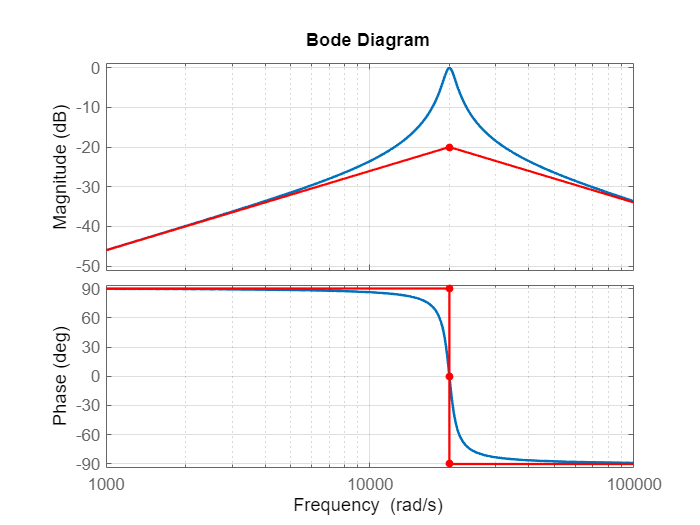

asymp(T_s);

#### **Simulacion**

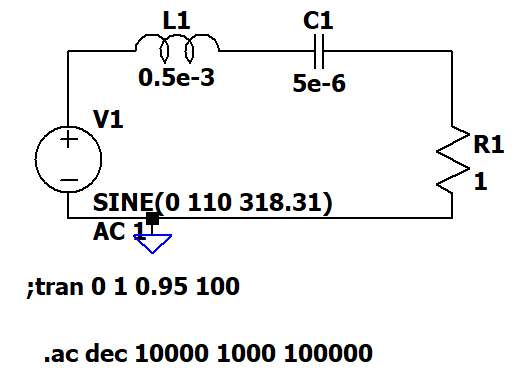

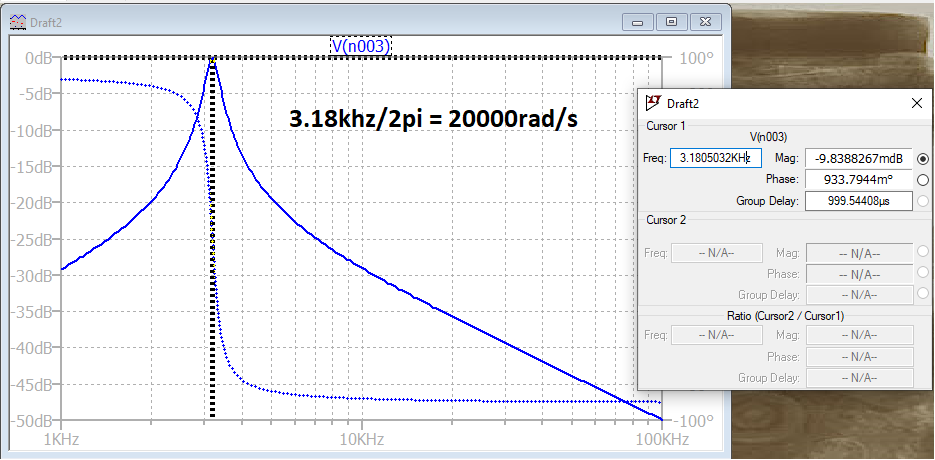

CIRCUITO EN RESONANCIA

note que se pierde cualquier desface de la senal de voltaje de la fuente con respecto al caida en la resistencia

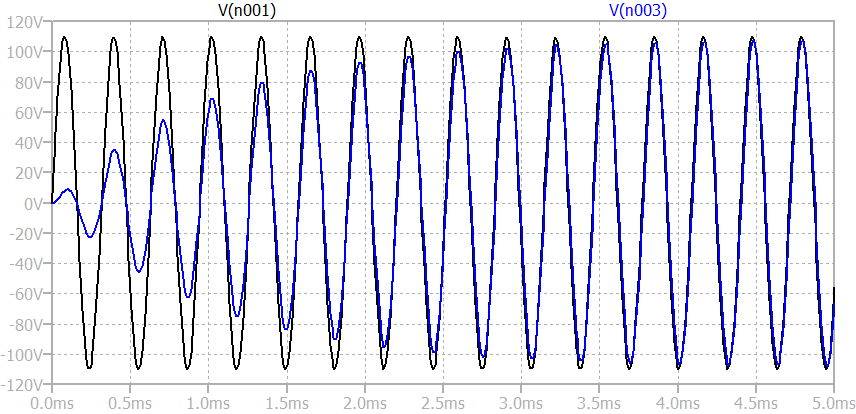

## Ejercicio 2

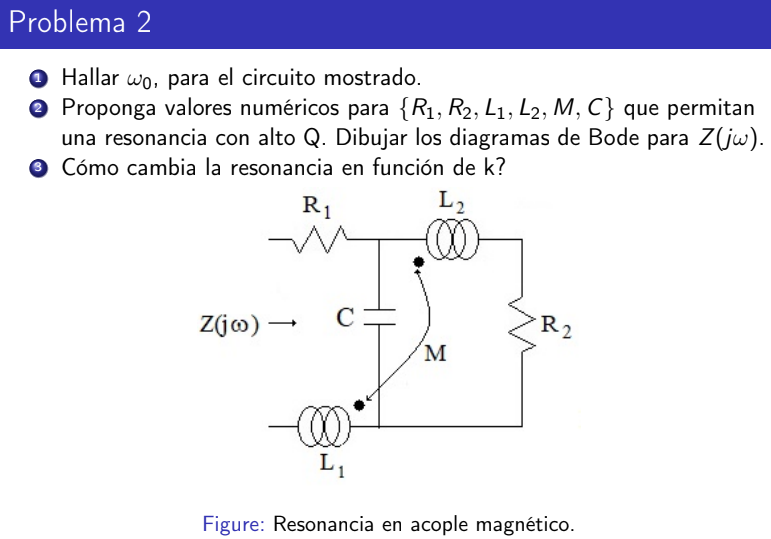

%valores de componentes
R1=1;
R2=5;
C1=1e-6;
L1=3e-3;
L2=8e-3;
k=0.5;
M1=k*sqrt(L1*L2) %k=M/SQRT(L1*L2) PARA UN ACOPLE DE K = 1

M1 =    2.4495e-03


format shortE

1)hallamos la frecuencia de resonancia apartir de la expresion de impedancia del sistema

syms R_1 R_2 C L_1 L_2 M s I_1 I_2 V_i w_0 w

equ1 = V_i==(R_1 + 1/(s*C) + L_1*s)*I_1 + (M*s - 1/(s*C))*I_2

$$equ1 = V_{i}=I_{1}\,\left(R_{1}+L_{1}\,s+\frac{1}{C\,s}\right)+I_{2}\,\left(M\,s-\frac{1}{C\,s}\right)$$

equ2 = 0==(R_2 + 1/(s*C) + L_2*s)*I_2 + (M*s - 1/(s*C))*I_1 

$$equ2 = 0=I_{2}\,\left(R_{2}+L_{2}\,s+\frac{1}{C\,s}\right)+I_{1}\,\left(M\,s-\frac{1}{C\,s}\right)$$


%METODO 1

I_2_1 = solve(equ1,I_2)   %DESPEJO 1_2 DE LA MALLA 2

$$I\_2\_1 = \frac{V_{i}-I_{1}\,\left(R_{1}+L_{1}\,s+\frac{1}{C\,s}\right)}{M\,s-\frac{1}{C\,s}}$$


% equ1=subs(equ2,I_2,I_2_1); %RESPLAZO I2 EN LA MALLA 1 PARA TENER TODO EN TERMINOS DE I_1

I_2 = solve(equ2,I_2) %I_1 ES LA MISMA CORRIENTE DE ENTRADA

$$I\_2 = -\frac{I_{1}\,\left(M\,s-\frac{1}{C\,s}\right)}{R_{2}+L_{2}\,s+\frac{1}{C\,s}}$$

I_i = solve(I_2_1==I_2,I_1)

$$I\_i = \frac{V_{i}}{\left(M\,s-\frac{1}{C\,s}\right)\,\left(\frac{R_{1}+L_{1}\,s+\frac{1}{C\,s}}{M\,s-\frac{1}{C\,s}}-\frac{M\,s-\frac{1}{C\,s}}{R_{2}+L_{2}\,s+\frac{1}{C\,s}}\right)}$$

% por lo tanto la impedancia de entrada se expresa asi
I_s = (I_i/V_i) 

$$I\_s = \frac{1}{\left(M\,s-\frac{1}{C\,s}\right)\,\left(\frac{R_{1}+L_{1}\,s+\frac{1}{C\,s}}{M\,s-\frac{1}{C\,s}}-\frac{M\,s-\frac{1}{C\,s}}{R_{2}+L_{2}\,s+\frac{1}{C\,s}}\right)}$$


I_s_s = subs(I_s,[R_1 R_2 C L_1 L_2 M],[R1 R2 C1 L1 L2 M1]) %simbolica

$$I\_s\_s = -\frac{1}{\left(\frac{\frac{5648138799537241\,s}{2305843009213693952}-\frac{1000000}{s}}{\frac{s}{125}+\frac{1000000}{s}+5}-\frac{\frac{3\,s}{1000}+\frac{1000000}{s}+1}{\frac{5648138799537241\,s}{2305843009213693952}-\frac{1000000}{s}}\right)\,\left(\frac{5648138799537241\,s}{2305843009213693952}-\frac{1000000}{s}\right)}$$

Z_s = 100/I_s_s;

w_o = (double(solve(Z_s==0,s)))  %frecuencia de corte\

w_o =   -3.7741e+02 + 0.0000e+00i
  -4.5018e+02 - 2.9716e+04i
  -4.5018e+02 + 2.9716e+04i


w_o = imag(w_o)

w_o =             0
  -2.9716e+04
   2.9716e+04


% w1_w2 = 

I_s = 100*sym2tf(I_s_s,0)  %100 el voltaje de la fuente

I_s =
 
         6.646e40 s^2 + 4.154e43 s + 8.308e48
  ---------------------------------------------------
  1.495e36 s^3 + 1.911e39 s^2 + 1.321e45 s + 4.985e47
 
Continuous-time transfer function.



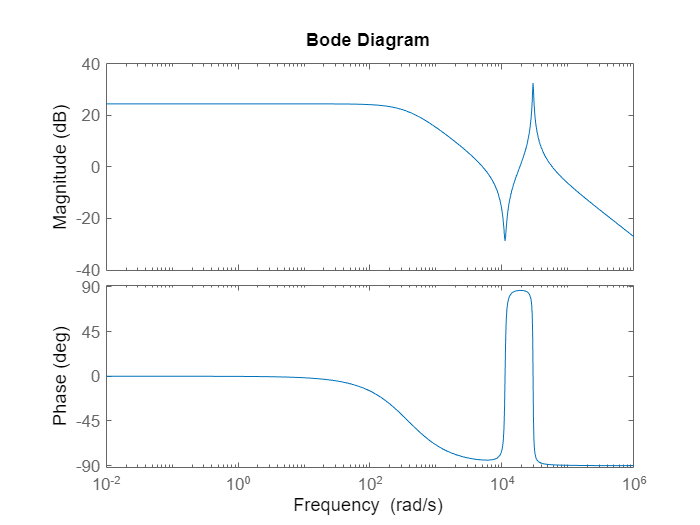

bode(I_s,{10e-3,1e6})

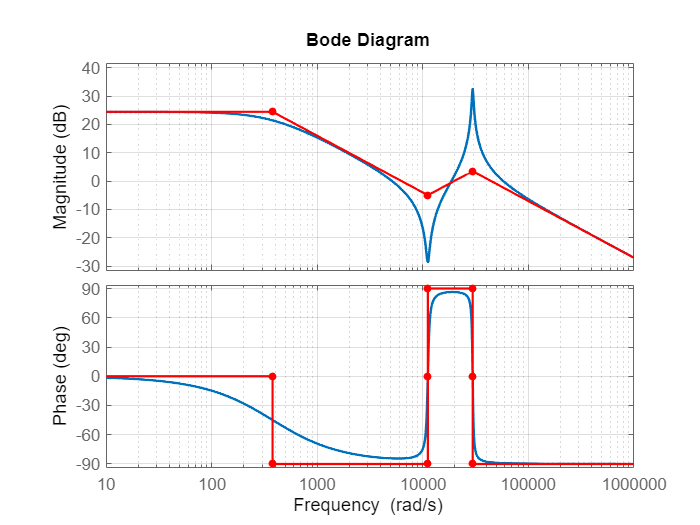

asymp(I_s)

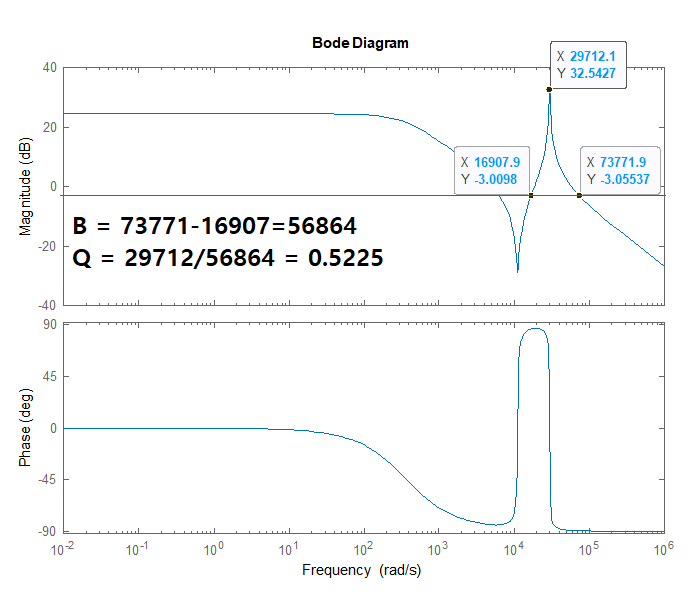

 ADMITANCIA

#### Simulacion

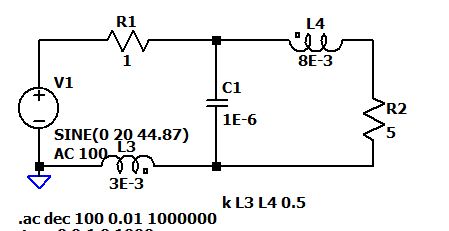

La herramienta asymp no puede graficar el bode con la funcion de impedancia, por tanto uso la de admitancia

frecuencia de resonancia    2.9716e+04 rad/s

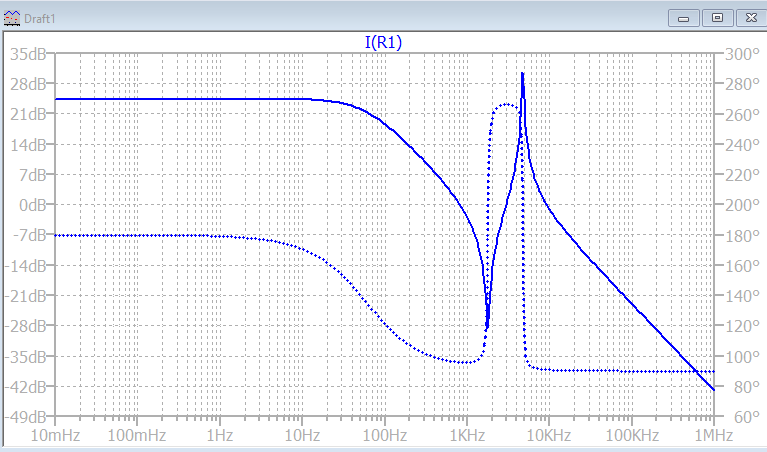

## Simulaciones para varios k

function Complejo = pol_com(M,A)  % magnitud, angulo

    Complejo = M * exp (deg2rad(A) * 1i); 

end

function [ tfobj ] = sym2tf( symobj, Ts) %pasa de sym a tf    Ts es el samplin, para continuas dejar en 0
    % SYM2TF convert symbolic math rationals to transfer function
    
    if isnumeric(symobj)
        tfobj=symobj;
        return;
    end
    
    [n,d]=numden(symobj);
    num=sym2poly(n);
    den=sym2poly(d);
    
    if nargin==1
        tfobj=tf(num,den);
    else
        tfobj=tf(num,den,Ts);
    end
end